# Examples for using the `newtons_method` function.

Copyright © 2021 Tamas Kis

## Example #1: Root of a simple function.

*Find the root of *$f\left(x\right)=x^2 -1$ *that is in the interval *$\left\lbrack 0,\infty \right)$.

For Newton's method, we also need $f^{\prime } \left(x\right)$. Differentiating $f\left(x\right)$,


$$f^{\prime } \left(x\right)=2x$$


Defining $f\left(x\right)$ and $f^{\prime } \left(x\right)$ in MATLAB,

f = @(x) x^2-1;
df = @(x) 2*x;

We want a root in the interval $\left\lbrack 0,\infty \right)$. Therefore, we use the initial guess $x_0 =10$. Finding this root using Newton's method,

root = newtons_method(f,df,10)

root = 1

## Example #2: Plot of intermediate root estimates.

*In example #1, we found the positive root of *$f\left(x\right)=x^2 -1$* using Newton's method. Now, produce a plot of the intermediate root estimates obtained by Newton's method before it returned the converged root.*

First, we define $f\left(x\right)$ and $f^{\prime } \left(x\right)$ in MATLAB like before.

f = @(x) x^2-1;
df = @(x) 2*x;

To obtain the intermediate root estimates, we simply need to define the `opts` structure, set its `return_all` field to true, and pass it to the `newtons_method` function. *(Note: we use the same initial guess as in Example #1).*

opts.return_all = true;
intermediate_roots = newtons_method(f,df,10,opts);

Plotting the intermediate root estimates,

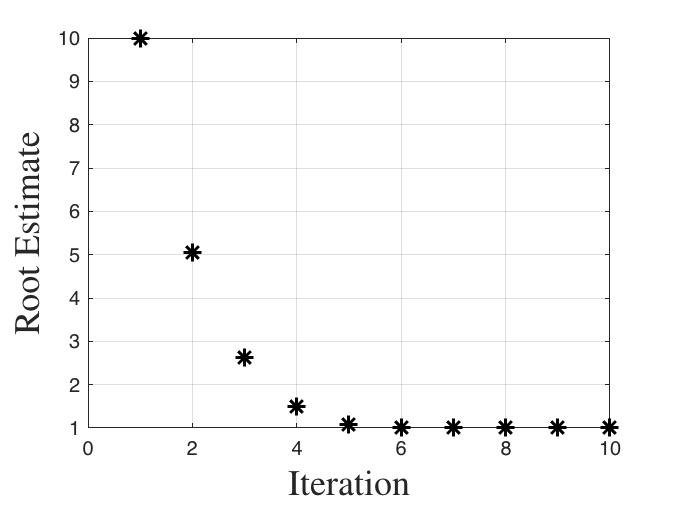

figure;
plot(intermediate_roots,'k*','markersize',9,'linewidth',1.5);
grid on;
xlabel('Iteration','interpreter','latex','fontsize',18);
ylabel('Root Estimate','interpreter','latex','fontsize',18);

We can also extract the converged root from `intermediate_roots`.

root = intermediate_roots(end)

root = 1

## Example #3: Intersection of two curves.

*Find the intersection of *$y=x^2$ and $y=\cos \left(x\right)$ *that is in the interval *$\left\lbrack 0,\infty \right)$.

Defining both functions and their derivatives,

% y = x^2 and its derivative
y1 = @(x) x.^2;
dy1 = @(x) 2.*x;

% y = cos(x) and its derivative
y2 = @(x) cos(x);
dy2 = @(x) -sin(x);

Let's plot both functions to see where their intersection lies.

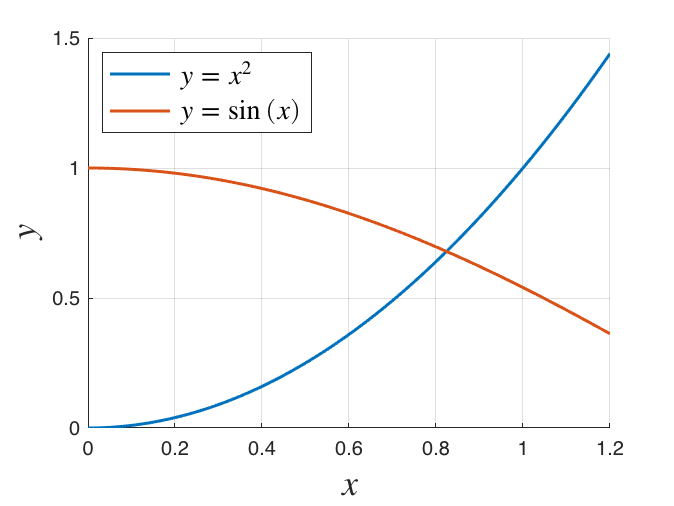

% defines interval for plotting
x = 0:0.01:1.2;

% plot
figure;
hold on;
plot(x,y1(x),'linewidth',1.5);
plot(x,y2(x),'linewidth',1.5);
hold off;
grid on;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel('$y$','interpreter','latex','fontsize',18);
legend('$y=x^{2}$','$y=\sin{(x)}$','interpreter','latex','fontsize',14,...
    'location','northwest');

Finding the intersection of the two functions is equivalent to finding the *root* of their difference. Therefore, we can use Newton's method on $y=\cos \left(x\right)-x^2$ with an initial guess of $x_0 =0\ldotp 8$ (picked using the plot above) to find the intersection.

diff = @(x) y2(x)-y1(x);
x_int = newtons_method(@(x) y2(x)-y1(x),@(x) dy2(x)-dy1(x),0.8)

x_int = 0.8241

Plotting to confirm that this is the true intersection,

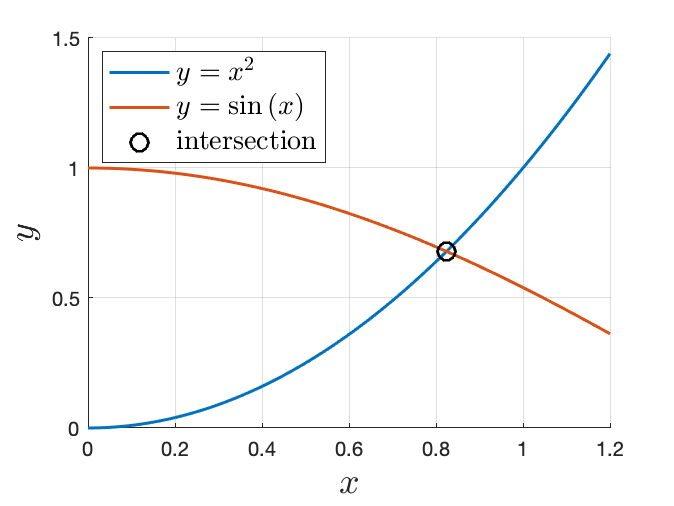

figure;
hold on;
plot(x,y1(x),'linewidth',1.5);
plot(x,y2(x),'linewidth',1.5);
plot(x_int,y1(x_int),'ko','markersize',9,'linewidth',1.5);
hold off;
grid on;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel('$y$','interpreter','latex','fontsize',18);
legend('$y=x^{2}$','$y=\sin{(x)}$','intersection','interpreter','latex',...
    'fontsize',14,'location','northwest');